% define optimization options
options = optimset('Display','iter','FunValCheck','on', ...
'MaxFunEvals',Inf,'MaxIter',Inf, ...
'TolFun',1e-6,'TolX',1e-6);
% define bounds for parameters
% a n b
paramslb = [-Inf 0 -Inf]; % lower bound
paramsub = [ Inf Inf Inf]; % upper bound
% define function that evaluates model given a vector
% of parameters (pp) and a matrix of x-values
modelfun = @(pp,xx) pp(1)*xx.^pp(2) + pp(3);
% perform optimization for first seed
params0 = [1 1 0];
[paramsA,resnormA] = lsqcurvefit(modelfun,params0,score1,score2,paramslb,paramsub,options);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          4          350877                      9.33e+05
     1          8          142784             10       2.06e+05      
     2         12         60521.2             20       5.36e+04      
     3         16         11504.9        34.9278       1.06e+05      
     4         20         3343.19        1.27111       6.45e+03      
     5         24         3343.19        1.87939       6.45e+03      
     6         28         3175.22       0.469846       1.96e+03      
     7         32         3093.01       0.939693       8.96e+03      
     8         36         2861.81       0.939693       7.94e+03      
     9         40         2660.09       0.939693       6.84e+03      
    10         44         2487.51       0.939693       5.98e+03      
    11         48         2487.51        1.87939       5.98e+03      
    12         52         2375.9

% perform optimization for second seed
params0 = [10 7 100];
[paramsB,resnormB] = lsqcurvefit(modelfun,params0,score1,score2,paramslb,paramsub,options);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          4     3.10275e+30                      9.99e+31
     1          8      3.4097e+13             10       1.03e+21      
     2         12          132345       0.178095        3.3e+16      
     3         16         97250.1    1.06356e-12       4.09e+03      

Local minimum possible.

lsqcurvefit stopped because the size of the current step is less than
the selected value of the step size tolerance.

<

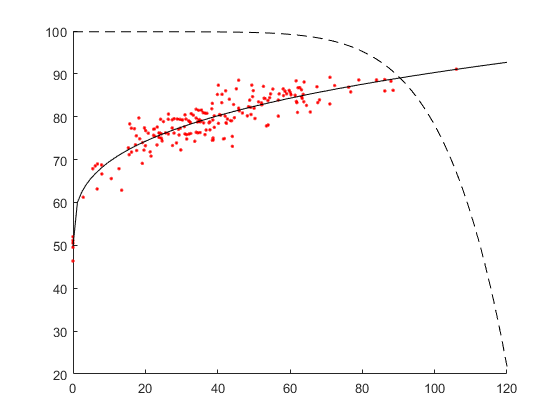

% visualize
figure; hold on;
scatter(score1,score2,'r.');
ax = axis;
xx = linspace(ax(1),ax(2),100);
hA = plot(xx,modelfun(paramsA,xx),'k-');
hB = plot(xx,modelfun(paramsB,xx),'k-');
%model that acheved lower squared error plot with regular line
%other model - with dashed (--) line
if resnormA < resnormB
    set(hB,'LineStyle','--');
else
    set(hA,'LineStyle','--');
end